load HW9.mat;

#### 1) Find the amplitude A and mean value 𝑎0 of the sampled pulse train data. Estimate the period of the signal T0 (in CT) by inspecting the time domain samples. Note that this is a rough estimate, since the true period may not be an integer multiple of the sampling rate.

A = max(x) - min(x); % find amplitude
a0 = mean(x); % find mean

Ts = 0.01;  
Fs = 1/Ts;

fprintf("A = %.4f, a0 = %.4f", A, a0);

A = 5.0000, a0 = 3.2381

By inspection of the vector, we can estimate T0 = 90-100ms. This is because the vector shows a fundamental period that varies between 9 and 10 samples.

#### 2) Choose a section of 1000 consecutive data points in the time domain for the fft analysis. Also include a plot of |X| vs. k (-500 to 499), the DFT index.

Define our selection window and get FFT

N1 = 1;
N2 = N1 + 999;
x_selected = x(N1:N2);
[X,f] = fdomain(x_selected,1./Ts);

Now plot the data

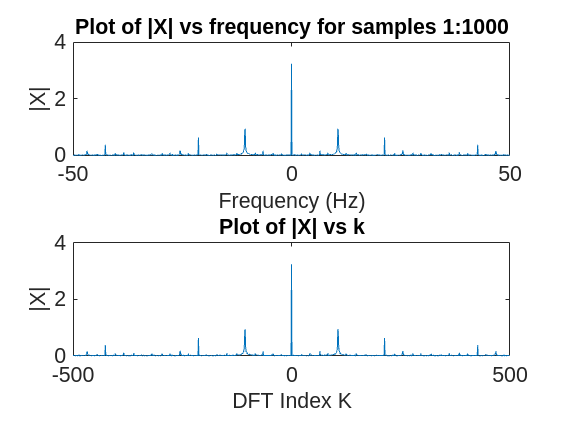

figure('Name','Sampled Data Plots');
subplot(2,1,1);
plot(f, abs(X));
xlabel('Frequency (Hz)');
ylabel('|X|');
title('Plot of |X| vs frequency for samples 1:1000');
fontsize(16,"points")
subplot(2,1,2);
k = -500:499;
plot(k, abs(X));
xlabel('DFT Index K');
ylabel('|X|');
title('Plot of |X| vs k');
fontsize(16,'points');

#### 3) Determine the fundamental frequency 𝑓0 of the pulse train from the spectrum graph in step 2. Determine the fundamental period T0 from 𝑓0. Is this result close to the result in step 1? Explain why these may be different, and which should be trusted more.

By visual inspection of the plot from step 2, the fundamental frequency is 10.7Hz

f0 = 10.7; % Hz
T0 = 1/f0; % s

We can probably trust this result more than the result from step 1. The time-domain data has alternating fundamental periods, which could indicate an issue with the sampling frequency being insufficient to properly capture changes in the data. The frequency-domain analysis allows for a more accurate representation of the data.

#### 4) Apply a 1000-point Hanning window to the sampled signal and determine the spectrum 𝑋ℎ𝑎𝑛𝑛of the windowed signal. Plot the magnitude |𝑋ℎ𝑎𝑛𝑛| of the spectrum vs. f in Hz, and also plot |𝑋ℎ𝑎𝑛𝑛| vs. k (-500 to 499).

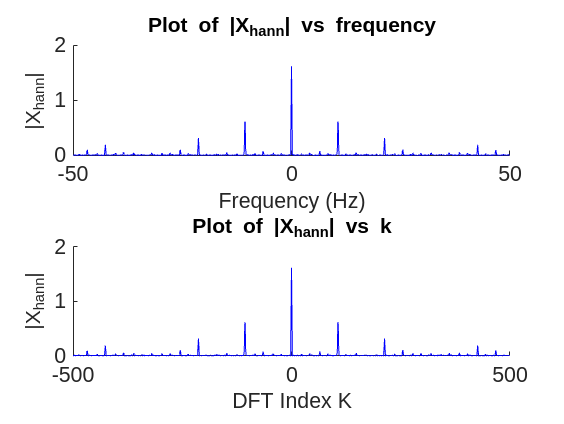

% Create the Hanning window
w = hann(1000);

% Apply hanning window to data
x_hann = x_selected .* w;
% FFT that shit
[X_hann, f] = fdomain(x_hann, Fs);
figure('Name','Hanning Window Plots');
subplot(2,1,1);
hold on
%plot(f, abs(X), 'r', 'LineWidth',1);
plot(f, abs(X_hann), 'b');
xlabel('Frequency (Hz)');
ylabel('|X_{hann}|');
title('Plot of |X_{hann}| vs frequency');
%legend('Selected Data','Windowed Data','Location','best')
fontsize(16,"points")

subplot(2,1,2);
hold on
%plot(k, abs(X), 'r', 'LineWidth',1.5);
plot(k, abs(X_hann), 'b');
xlabel('DFT Index K');
ylabel('|X_{hann}|');
title('Plot of |X_{hann}| vs k');
%legend('Selected Data','Windowed Data','Location','best')
fontsize(16,'points');

#### 5) Calculate the Discrete Time Fourier Series (DTFS) coefficients for one period of the sample data

Calculate the first four DTFS coefficients for 1 period, using the formula d = N1/N0

period = x(6:16);
N1 = 6;
N0 = 4;
d = N1/N0;

a = @(k) abs((A * sin(k * pi * d)) ./ (N0 * sin(k * pi / N0)));
a_11 = a(1);
a_21 = a(2);
a_31 = a(3);
a_41 = a(4);
fprintf("a1 = %.4f, a2 = %.4f, a3 = %.4f, a4 = %.4f \n", a_11, a_21, a_31, a_41);

a1 = 1.7678, a2 = 0.0000, a3 = 1.7678, a4 = 7.5000 


Calculate the first four DTFS coefficients for the entire data stream, using d = a0/A

d = a0/A;
% calculate N0 by dividing total data length by number of 0->A transitions
differences = diff(x);
changes = sum((differences >= 4.9));
N0 = length(x)./changes;
a = @(k) abs((A * sin(k * pi * d)) ./ (N0 * sin(k * pi / N0)));

a_12 = a(1);
a_22 = a(2);
a_32 = a(3);
a_42 = a(4);
fprintf("a1 = %.4f, a2 = %.4f, a3 = %.4f, a4 = %.4f \n", a_12, a_22, a_32, a_42);

a1 = 1.4503, a2 = 0.6867, a3 = 0.1127, a4 = 0.5249 


Calculate the magnitude of the DTFS coefficients corresponding to the first four harmonics in the 1000-length selected data from part (2). 

We need to find the positive index corresponding to the fundamental frequency peak. From the plot from part (2), we see that the index is 107. Then, we can find our magnitudes

Np1 = 107; % index of fundamental freq
a = @(k) abs(X(500+k*Np1));
a_13 = a(1);
a_23 = a(2);
a_33 = a(3);
a_43 = a(4);
fprintf("a1 = %.4f, a2 = %.4f, a3 = %.4f, a4 = %.4f", a_13, a_23, a_33, a_43);

a1 = 0.9380, a2 = 0.6284, a3 = 0.0582, a4 = 0.0203

Calculate the magnitude of the DTFS coefficients corresponding to the first four harmonics in the 1000-length windowed data from part (4)

We once again see that the positive index corresponding to the fundamental frequency peak is 107. Then, we can find our magnitudes

Np1 = 107; % index of fundamental freq
a = @(k) abs(X_hann(k.*Np1+500));

a_14 = a(1);
a_24 = a(2);
a_34 = a(3);
a_44 = a(4);
fprintf("a1 = %.4f, a2 = %.4f, a3 = %.4f, a4 = %.4f", a_14, a_24, a_34, a_44);

a1 = 0.6102, a2 = 0.3165, a3 = 0.0409, a4 = 0.0884